# Introductory Example to Multigrid Method

%% Introductory Example to Multigrid Method

% This script introduces the multigrid method by showing and using functions
% defined in separate files.


## Functions

% Let's take a look at the function `grid_with_boundary.m`:

type grid_with_boundary.m


%% Grid with Boundary Function
function f = grid_with_boundary(k,H1,H2)
    n = 2^k;
    
    % Grid:
    f = zeros(n+1, n+1);
    
    % Boundary Conditions:
    % Bottom
    f(1, 1:(n/2 +1)) = linspace(13, 5, n/2 +1);
    f(1, (n/2+1):(3*n/4)) = 5;
    f(1, (3*n/4+1):(n+1)) = linspace(5, 13, n/4+1);
    
    % Top
    f(n+1, 1:n+1) = 21;
    
    % Left
    f(1:(3*n/8+1), 1) = linspace(13, H1, 3*n/8+1);
    f((n/2+1):n+1, 1) = linspace(H1, 21, n/2+1);
    
    % Right
    f(1:(n/2+1), n+1) = linspace(13, H2, n/2+1);
    f((5*n/8+1):n+1, n+1) = linspace(H2, 21, 3*n/8+1);

    % Heaters:
    f = add_heaters(f,H1,H2);
end



% The function creates a grid with specific boundary conditions based on the
% input parameter `k`. The grid will be used as the initial setup for our
% simulations.

%% Jacobi Step Function
% Now, let's examine the `jacobi_step.m` function:

type jacobi_step.m


%% Jacobi Step Function
function T_prime = jacobi_step(T)
    [m, n] = size(T);
    T_prime = T;

    % iterate over interior:
    for i = 2:m-1
        for j = 2:n-1
            % Jacobi update
            T_prime(i, j) = (T(i+1, j) + T(i-1, j) + T(i, j-1) + T(i, j+1)) / 4;
        end
    end
end



% This function performs one Jacobi iteration, updating the grid based on
% neighboring values.

%% Add Heaters Function
% The `add_heaters.m` function adds heat sources to specific locations on the grid:

type add_heaters.m


%% Add Heaters Function
function T = add_heaters(T,H1,H2)
    n = size(T, 1) - 1;
    
    T((3*n/8+1):(n/2+1), 1:(n/8+1)) = H1;
    T((n/2+1):(6*n/8+1), (7*n/8+1):n+1) = H2;
end



% This function modifies the grid by applying heat sources at defined positions.

%% Simulation Function
% Finally, let's look at the `simulation.m` function:

type simulation.m


%% Simulation Function
function results = simulation(T, epsilon, num_steps,H1,H2)
    results = {T};

    for i = 1:num_steps
        T_prime = jacobi_step(T);
        T_prime = add_heaters(T_prime,H1,H2);

        results{end+1} = T_prime;
        
        if max(abs(T_prime(:) - T(:))) < epsilon
            return;
        end

        T = T_prime;
    end
end



% This function runs the simulation by iteratively applying the Jacobi method
% and adding heaters at each step.


## Coarse Grid, to get an impression of the steady state

%% Initial Setup
H1 = 140; %% Temperature of the heater on the left
H2 = 200;%% Temperature of the heater on the right
T = grid_with_boundary(4,H1,H2);

%% Note that only the boundary conditions are in T now.

%% Run Simulation
tic;
results = simulation(T, 1e-10, 5000, H1, H2);
toc;

Elapsed time is 0.014728 seconds.


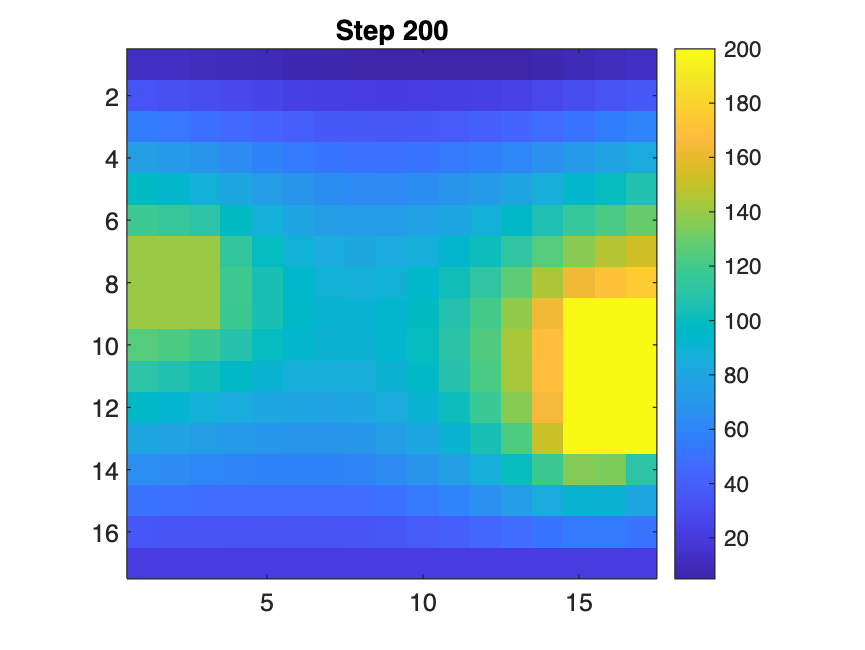


%% Visualization
figure;
for i = 1:200
    imagesc(results{i});
    colorbar;
    title(sprintf('Step %d', i));
    axis equal tight;
    drawnow;
    pause(0.01);
end

## Better Initial Condition

type initial_condition.m


function T_new = initial_condition(T)
    [m, n] = size(T);
    T_new = T;

    for i = 2:m-1
        for j = 2:n-1
            % weighted average of boundaries:
            T_new(i, j) = (j * T(i, n) + (n + 1 - j) * T(i, 1) + ...
                (m + 1 - i) * T(1, j) + i * T(m, j)) / (m + n + 2);
        end
    end
end



% This function proivides better initialization for the iterative solver.


## Next, a finer grid, and better initial condition

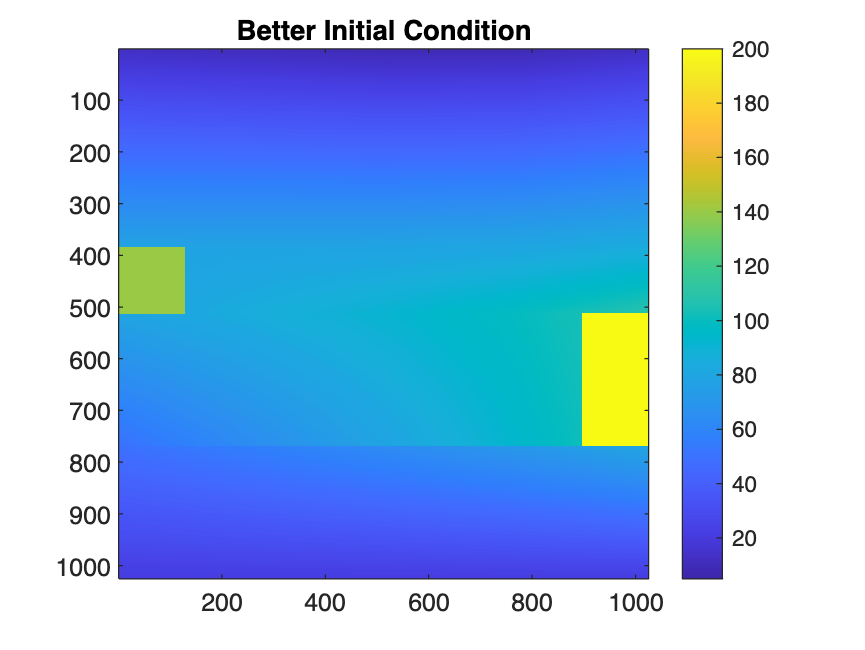

%% Test Better Initial Condition
TT = grid_with_boundary(10,H1,H2);
TT_prime = initial_condition(TT);
TT_prime = add_heaters(TT_prime, H1, H2);

figure;
imagesc(TT_prime);
colorbar;
axis equal tight;
title('Better Initial Condition');


%% Run Simulation with Better Initial Condition
tic;
results2 = simulation(TT_prime, 1e-5, 500, H1, H2);
toc;

Elapsed time is 4.268875 seconds.


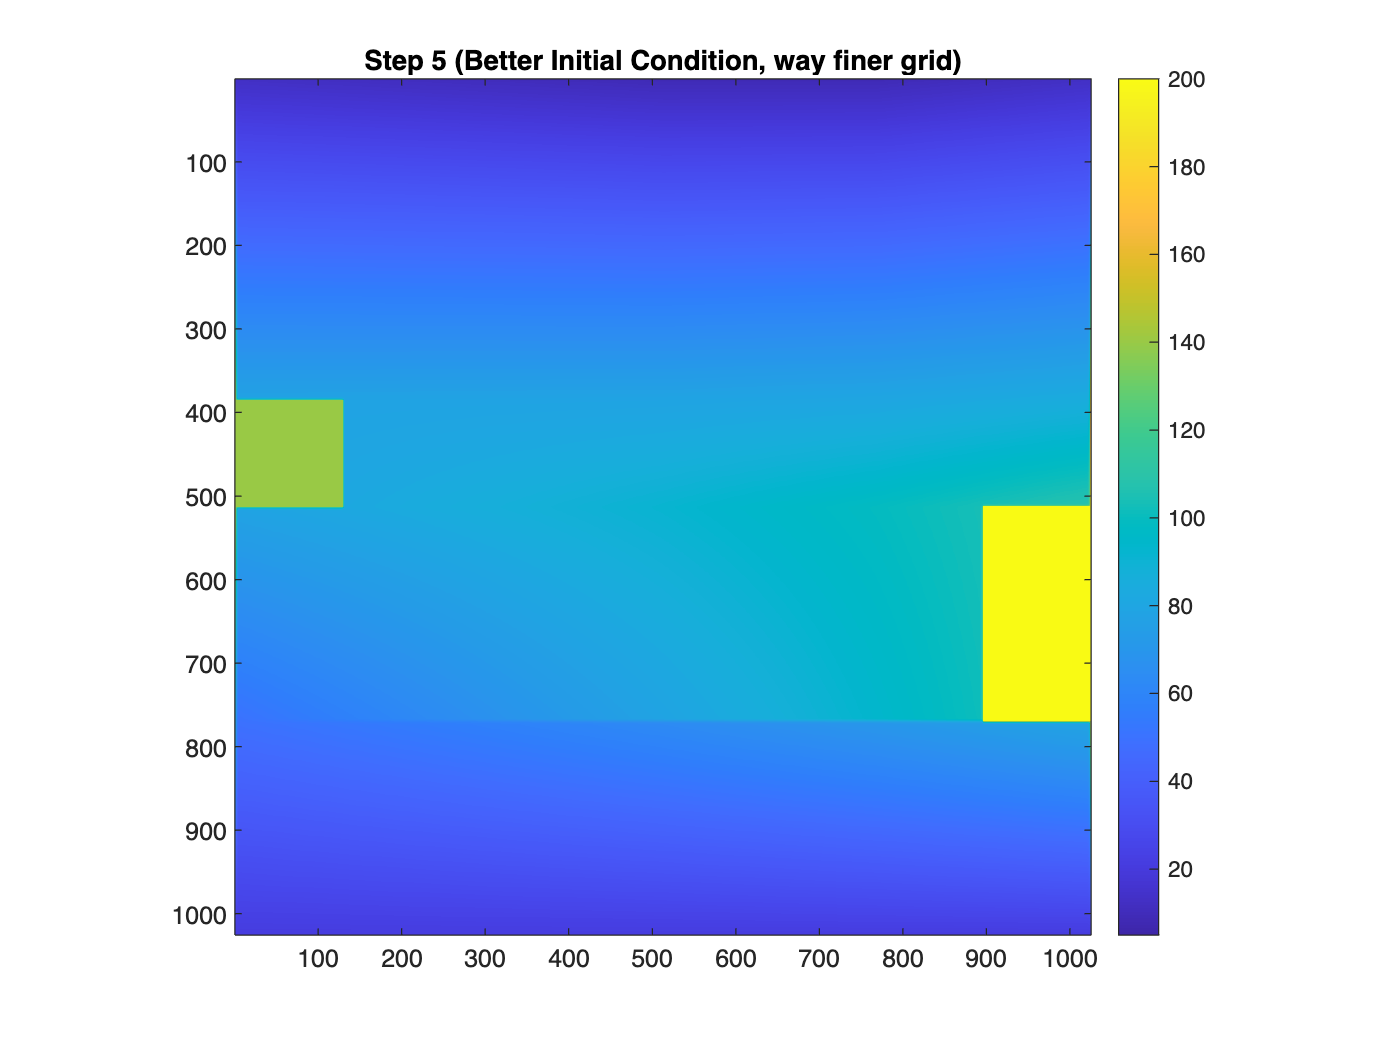


%% Visualization of solving on finer grid with better Initial Condition Results
figure;
for i = 5:5:length(results2)
    imagesc(results2{i});
    colorbar;
    title(sprintf('Step %d (Better Initial Condition, way finer grid)', i));
    axis equal tight;
    drawnow;
    pause(0.1);
end


%% You can tell, this method is clearly inefficient.


## Coarse Grid to Fine Grid

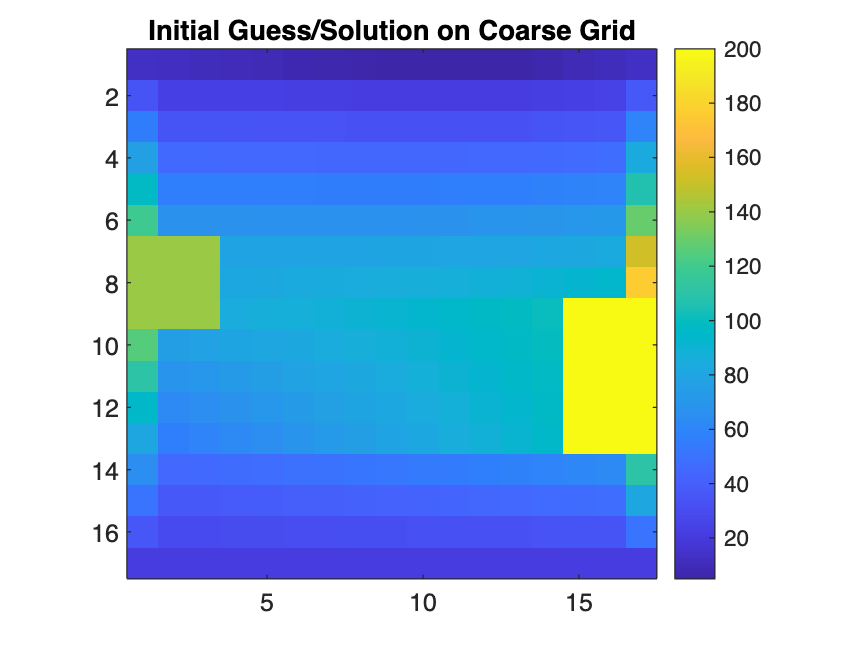

coarse = initial_condition(grid_with_boundary(4,H1,H2));
coarse = add_heaters(coarse,H1,H2);

figure;
imagesc(coarse);
colorbar;
axis equal tight;
title('Initial Guess/Solution on Coarse Grid');

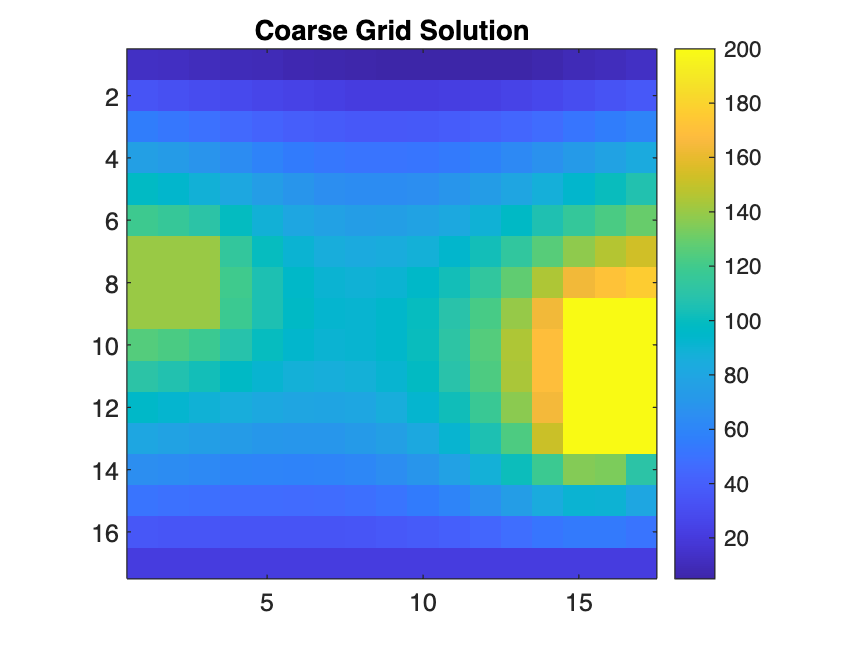


coarse_results = simulation(coarse, 1e-10, 5000, H1, H2);

figure;
imagesc(coarse_results{end});
colorbar;
axis equal tight;
title('Coarse Grid Solution');

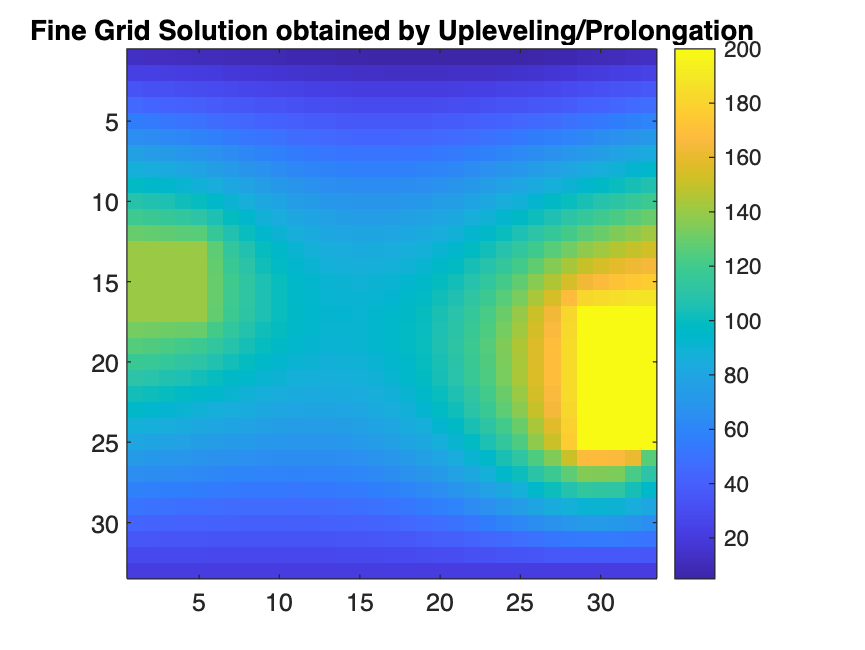


next = uplevel(coarse_results{end}, H1, H2);
next = add_heaters(next, H1, H2);
figure;
imagesc(next);
colorbar;
axis equal tight;
title('Fine Grid Solution obtained by Upleveling/Prolongation');


%%This serves as our initial condition for the multigrid method.


## Our First Multigrid

% Run Multilevel
starting_point = initial_condition(grid_with_boundary(4,H1,H2));
starting_point = add_heaters(starting_point,H1,H2);

tic;
[last, ks, iterations, level_solutions] = multilevel(starting_point, 10, H1, H2);
toc;

Elapsed time is 35.429851 seconds.



% Display Results
disp('Grid levels:');

Grid levels:


disp(ks);

     4     5     6     7     8     9    10



disp('Iterations at each level:');

Iterations at each level:


disp(iterations);

         478        1265        3490        5001        5001        4237        3106




cost = iterations(7) + iterations(6)/4 + iterations(5)/16 + iterations(4)/64 + ...
       iterations(3)/256 + iterations(2)/1024 + iterations(1)/2048;
disp(['Total computational cost: ', num2str(cost)]);

Total computational cost: 4571.0547


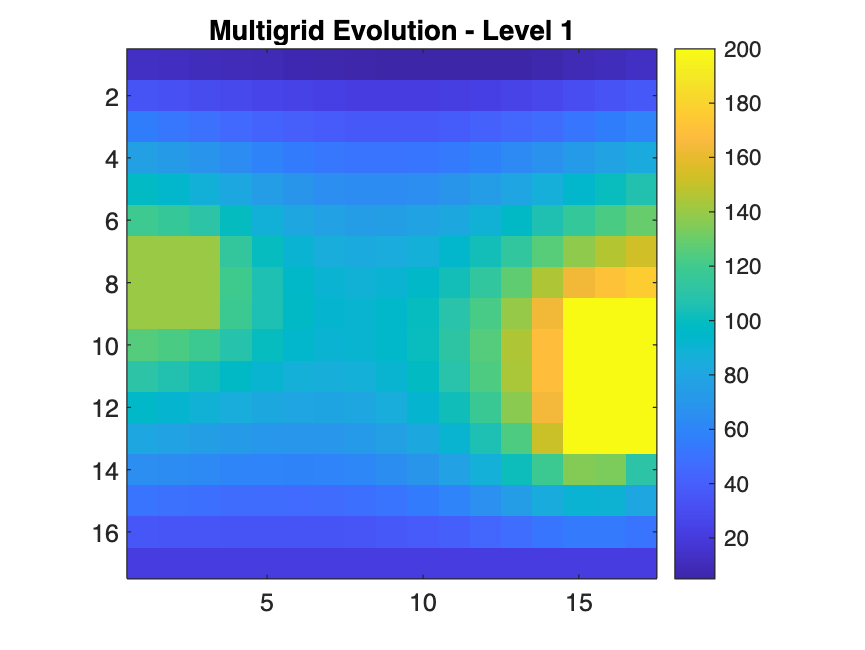

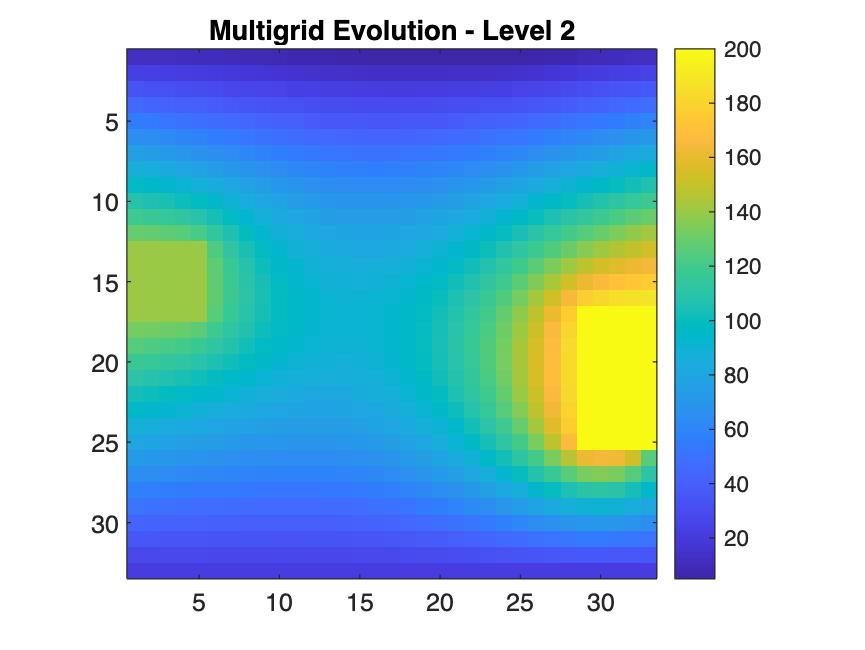

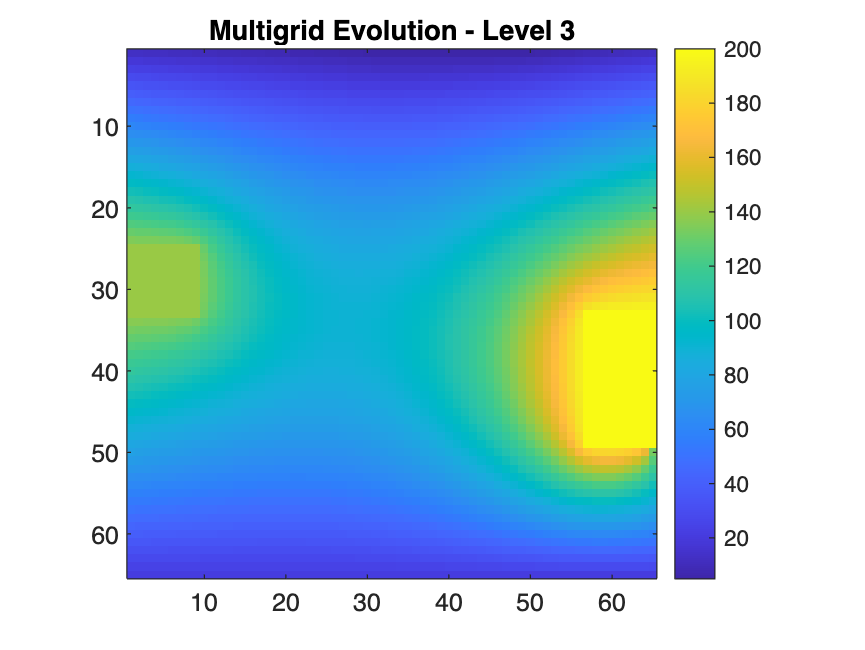

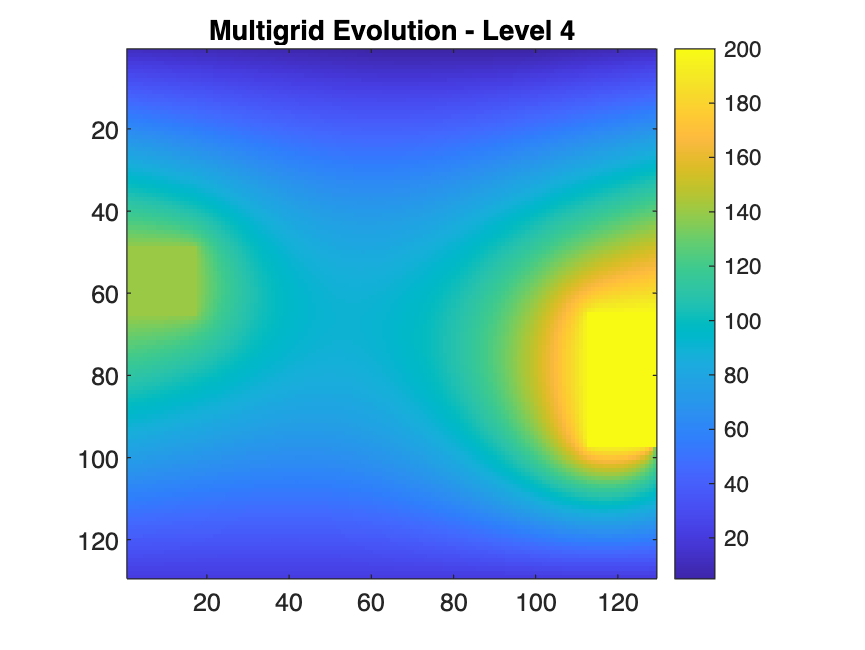

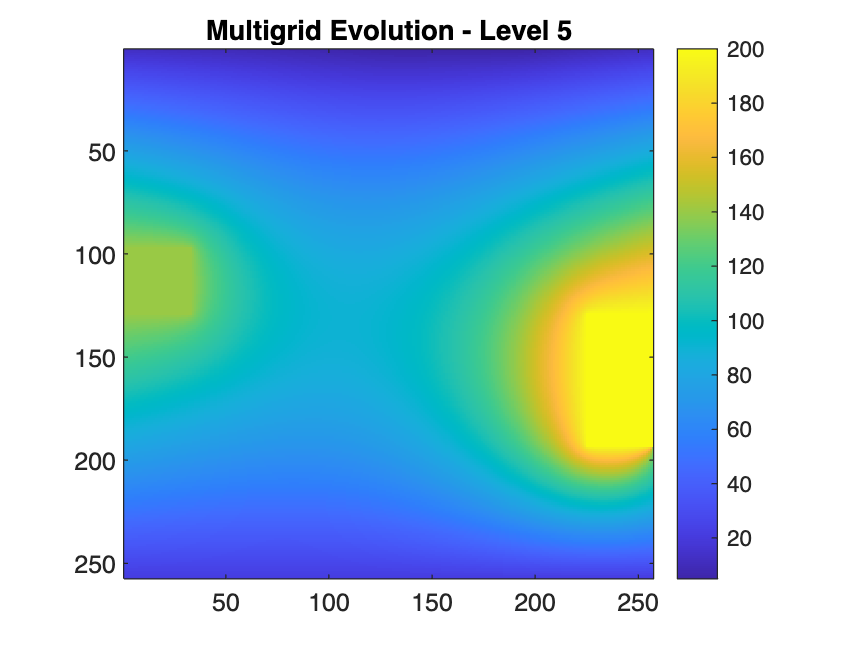

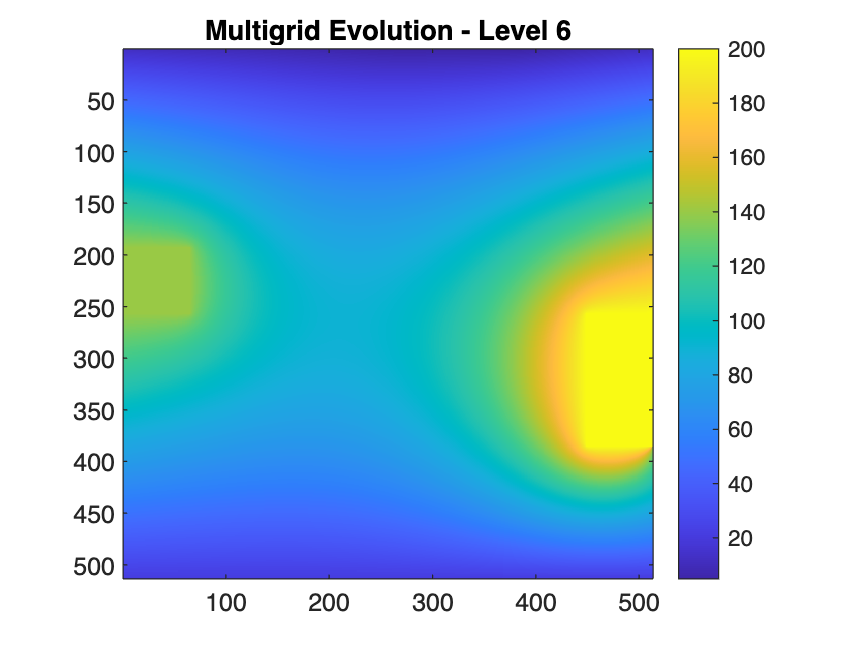

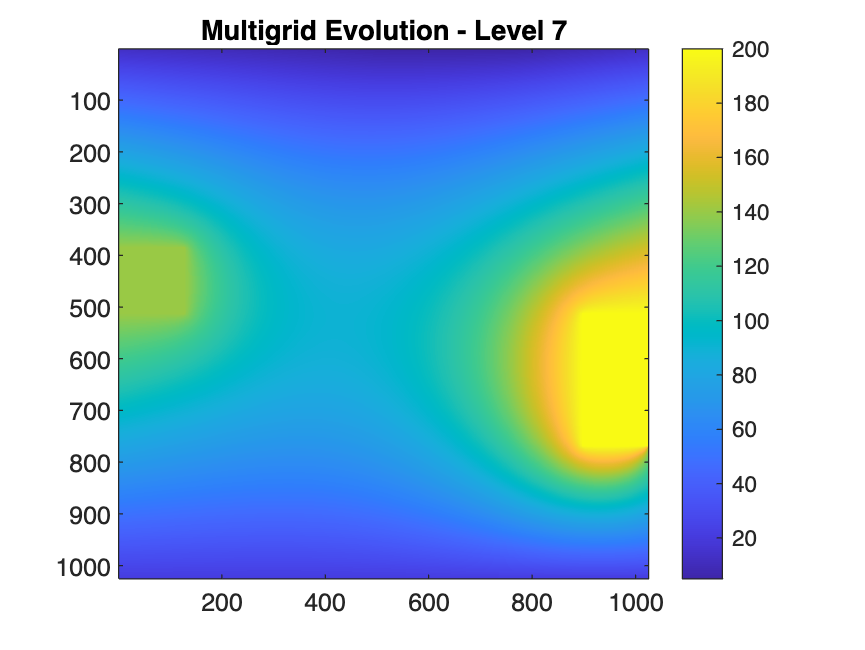


% Plotting solutions on each level
for i = 1:length(level_solutions)
    figure('Position', [100, 100, 800, 600]);
    imagesc(level_solutions{i});
    colorbar;
    axis equal tight;
    title(sprintf('Multigrid Evolution - Level %d', i));   
end

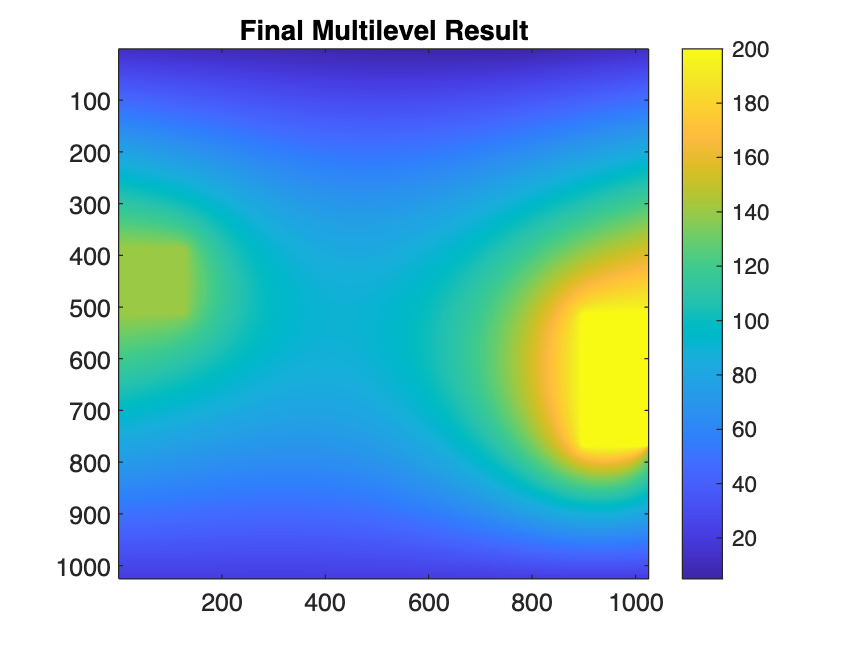


% Display final result
figure;
imagesc(last);
colorbar;
axis equal tight;
title('Final Multilevel Result');